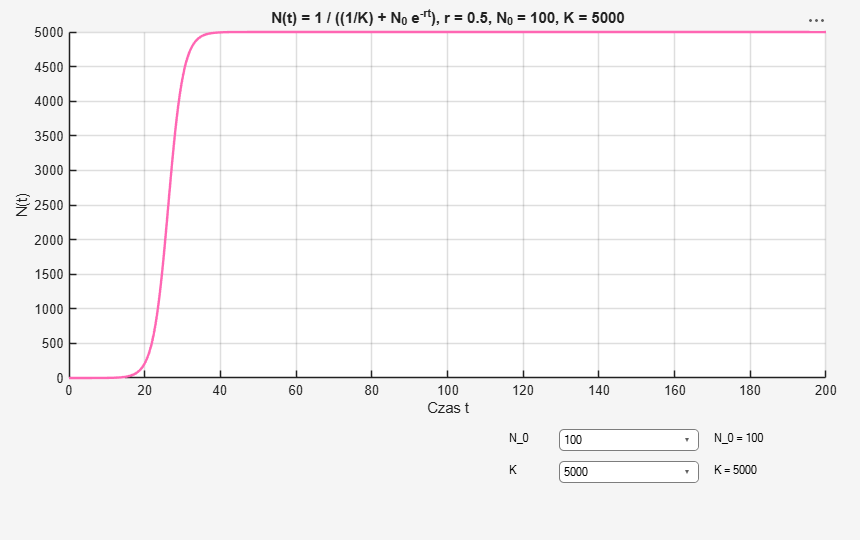

n0Values = [5 10 25 50 100 250 500 1000];
kValues = [1000 2000 5000 10000];
t = linspace(0, 200, 500);
r = 0.5;

f = figure('Name', 'Wykres funkcji', 'NumberTitle', 'off', ...
    'Position', [100 100 860 540]);

ax = axes('Parent', f, 'Position', [0.08 0.30 0.88 0.64]);
grid(ax, 'on')
hold(ax, 'on')

n0 = 100;
k = 5000;
n = 1 ./ ((1 ./ k) + n0 .* exp(-r .* t));

p = plot(ax, t, n, 'LineWidth', 1.8, 'Color', [1 0.4 0.7]);

xlabel(ax, 'Czas t')
ylabel(ax, 'N(t)')
title(ax, sprintf('N(t) = 1 / ((1/K) + N_0 e^{-rt}), r = %.1f, N_0 = %d, K = %d', r, n0, k))

uicontrol(f, 'Style', 'text', 'Position', [510 90 70 20], ...
    'String', 'N_0', 'HorizontalAlignment', 'left');

n0Popup = uicontrol(f, 'Style', 'popupmenu', 'Position', [560 88 140 24], ...
    'String', cellstr(string(n0Values)), ...
    'Value', find(n0Values == n0, 1), ...
    'UserData', n0Values, ...
    'Callback', @(src, ~) updatePlot(ax, p, t, r, src, kPopup, n0ValueText, kValueText));

n0ValueText = uicontrol(f, 'Style', 'text', 'Position', [715 90 110 20], ...
    'String', sprintf('N_0 = %d', n0), 'HorizontalAlignment', 'left');

uicontrol(f, 'Style', 'text', 'Position', [510 58 70 20], ...
    'String', 'K', 'HorizontalAlignment', 'left');

kPopup = uicontrol(f, 'Style', 'popupmenu', 'Position', [560 56 140 24], ...
    'String', cellstr(string(kValues)), ...
    'Value', find(kValues == k, 1), ...
    'UserData', kValues, ...
    'Callback', @(src, ~) updatePlot(ax, p, t, r, n0Popup, src, n0ValueText, kValueText));

kValueText = uicontrol(f, 'Style', 'text', 'Position', [715 58 110 20], ...
    'String', sprintf('K = %d', k), 'HorizontalAlignment', 'left');

updatePlot(ax, p, t, r, n0Popup, kPopup, n0ValueText, kValueText);


function updatePlot(ax, p, t, r, n0Popup, kPopup, n0ValueText, kValueText)
n0Values = n0Popup.UserData;
kValues = kPopup.UserData;

n0 = n0Values(n0Popup.Value);
k = kValues(kPopup.Value);

n = 1 ./ ((1 ./ k) + n0 .* exp(-r .* t));
p.YData = n;

title(ax, sprintf('N(t) = 1 / ((1/K) + N_0 e^{-rt}), r = %.1f, N_0 = %d, K = %d', r, n0, k))
n0ValueText.String = sprintf('N_0 = %d', n0);
kValueText.String = sprintf('K = %d', k);
end
rGroup.SelectionChangedFcn = @(src, ~) updatePlot(ax, p, t, src, n0Popup, kPopup, n0ValueText, kValueText);

Invalid or deleted object.

n0Popup.Callback = @(src, ~) updatePlot(ax, p, t, rGroup, src, kPopup, n0ValueText, kValueText);
kPopup.Callback = @(src, ~) updatePlot(ax, p, t, rGroup, n0Popup, src, n0ValueText, kValueText);

rGroup.SelectedObject = rButtons(3);
updatePlot(ax, p, t, rGroup, n0Popup, kPopup, n0ValueText, kValueText);